# Matlab Tutorials

Das *LiveScript* zu dem Tutorial 2.

Aufgaben auch bei den [Matlab Tutorials von MathWorks](https://matlabacademy.mathworks.com/).

## Tutorial 2.1

- Indexierung von Matrizen

- Berechnungen mit Matrizen

Zunächst erzeugen wir uns Daten mit denen wir arbeiten können:

data = [zeros(5,2) rand(5,1) ones(5,3)]

ans =      1


**Wichtig:** Das "=" ist in Matlab ein Zuweisungsoperator! Auf der *rechten Seite* werden Dinge *berechnet* und in der Variable auf der *linken Seite gespeichert*.

Um nun auf die Daten zugreifen zu können gibt es unterschiedliche Möglichkeiten:

data(1)      % 1 Element (spaltenweise)

ans =      0


data(11)     % entspricht hier: Zeile 1 und Spalte 3

ans =      1


data(end)    % letztes Element

ans =      0


ans =      0


data(3,2)    % Element aus Zeile 3 und Spalte 2

ans =      1


data(3,end)  % Element aus Zeile 3 und letzter Spalte

ans =      0



data(3,:)    % alle Elemente der 3. Zeile

test_vec =    -1.0000
   -0.7778
   -0.5556
   -0.3333
   -0.1111
    0.1111
    0.3333
    0.5556
    0.7778
    1.0000


data(:,1)    % alle Elemente der 1. Spalte


test1 =      0
     0
     0
     0
     0
     0
     0
     1
     1
     1


idx = 1:2:5  % Indizes, die benötigt werden

test2 =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


data(idx, 1) % ausgewählte Elemente der ersten Spalte

Berechnungen mit Matrizen und Vektoren

data(3,:) + 1 % elementweise Addition

test3 =      0
     0
     0
     0
     0
     1
     1
     1
     0
     0


data(3,:) * 2 % elementweise Multiplikation

test4 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



data(2,:) + data(3,:) % elementweise Addition von Vektoren

Matrizenmultiplikation ([Wikipedia](https://de.wikipedia.org/wiki/Matrizenmultiplikation)):

A = [3 2 1; 1 0 2];
B = [1 2; 0 1; 4 0];
A * B                  % normale Matrizenmultiplikation

ones(3,2) .* ones(3,2) % elementweise Multiplikation von Matrizen
ones(2,3) .* ones(3,2) % Fehler: Matrizen haben nicht die gleichen Dimensionen

Analyse von Daten:

dim = size(data)    % Anzahl der Elemente der Matrix (dim(1)xdim(2))
[r, c] = size(data) % Anzahl der Elemente der Matrix (RxC)

[val, idx] = max(data(1,:)) % größter Wert (val) und Index (idx) eines Vektors

min(data)           % spaltenweise Minimum, oder: min(data,[],1)
min(data, [], 2)    % zeilenweise Minimum

max(data)           % spaltenweise Maximum, oder: max(data,[],1)
max(data, [], 2)    % zeilenweise Maximum

mean(data)          % spaltenweise Mittelwert, oder: mean(data,1)
mean(data, 2)       % zeilenweise Mittelwert

data_rounded = round(data) % gerundete Daten

## Tutorial 2.2

- Skripte in Matlab

- Skripte: editieren und ausführen

Bisher haben wird nur mit der Command Line gearbeitet, wenn man bestimmte Abläufe allerdings speichern will, dann kann man dafür Skripte verwenden.

Matlab Skripte haben die Dateiendung ".m" und lassen sich mit jedem Texteditor bearbeiten. Mit dem folgenden Befehl wird der Matlab Texteditor geöffnet und die Datei "test_skript.m" aufgerufen:

edit test_skript.m

Nun können dort alle Aufrufe, die vorher in der Command Line ausgeführt werden eingegeben werden. Anschließend gibt es drei Möglichkeiten das Skript auszuführen:

- Klick auf den Play Knopf "Run".

- Während das Skript ausgewählt ist die Taste "F5" drücken.

- Auf der Command Line den namen des Skriptes (ohne Dateiendung) eintippen und ausführen.

Die ersten Zeilen des Skriptes können beispielsweise so aussehen:

% Script to do something usefull
%
% This script contains some very usefull calculations from the
% "Matlab Tutorials".

% Author: Julian Kahnert (c) IHA @ Jade Hochschule

clear
close all


Die ersten (durch ein "%" auskomentierten) Zeilen eines Skriptes, die  werden in der Help ("help test_skript") oder Dokumentation ("doc test_skript") angezeigt. Sie sollten Aufschluss geben, was innerhalb des Skriptes passiert bzw. wofür es hilfreich sein kann. Eine Leerzeile schließt den Teil der in der Help zu sehen ist ab. Anschließend sollte der Autor des Skriptes erwähnt werden.

Die Befehle "clear" und "close all" verwende ich in den meisten Skripten, um den Workspace zu leeren und alle geöffneten Plots zu schließen. Hiernach können die Berechnungen stattfinden!

## Tutorial 2.3

- Datentyp: Logicals

- IF-ELSE Verzweigungen

In Matlab gibt es die logischen Werte "true" und "false" (häufig auch 1 bzw. 0 abegkürzt).  Hier ein Liste mit Beispielen für mögliche logische Operationen mit zwei Werten:

1 < 3
1 > 3
1 <= 3
1 >= 3

ans = 70

1 == 3

ans = 82

1 ~= 3

ans = 75.7600

~(1 < 3)

ans =     70
    76
    82


Diese Operationen können auch zwischen einem Vektor und einem Wert oder einem Vektor und einem Vektor durchgeführt werden:

test_vec = linspace(-1, 1, 10).'

val = 1795

idx = 52

ans = honda civic                      

test1 = test_vec > 0.5                     % Vektor vs. Wert
test2 = test_vec > zeros(10, 1)            % Vektor vs. Vektor

Verknüpfung von zwei logischen Vektoren:

test3 = (test_vec > 0) & (test_vec < 0.7)    % Verknüpfung: UND
test4 = (test_vec > 0) | (test_vec < 0.7)    % Verknüpfung: ODER

Ein Beispiel für die logischen Operatoren werden wir jetzt in dem vorher erzeugten Skript "test_skript.m" erstellen. Da wir das Skript "test_skript" bereits erzeugt haben, öffnet der nachfolgende Befehl dieses Skript:

edit test_skript.m

ans = 3.4413e+03

Hier können wir nun den nachfolgenden Code einfügen:

% berechne A

ans = 3.0787e+03

A = randn(1);

ans = 2.4535e+03


% berechne B

ans =     88
    88
    88
    85
    84
    90
    92
   NaN
    74
    68


if A > 0.7
    B = sqrt(A);
    

ans = 81.4667

elseif A < -0.7
    B = A^2;
    
else
    B = 0;
    
end

In diesem Skript wird eine IF-ELSE Bedingung als mögliche Anwendung für die logischen Operatoren verwendet.

Zunächst wird eine Zufallszahl aus einer Standard-Normalverteilung erzeugt. Anschließend wird diese Zahl mit dem Wert 0.7 verglichen. Sofern A größer ist als 0.7, die Bedingung "A > 0.7" also *wahr* ist, wird die Zeile "B = sqrt(A);" ausgeführt. Ansonsten wird "A < -0.7" berechnet, falls diese Bedinung *wahr* ist, wird die Zaile "B = A^2;" berechnet. Falls keiner dieser beiden Fälle zutrifft, wird "B = 0;" ausgeführt.

## Tutorial 2.4

- Beispiel: Datenanalyse

- Plots erstellen und bearbeiten

Die weiteren Aufgaben möchte ich anhand von Daten durchführen, die in Matlab bereits gespeichert sind. Hierfür erstellen wir erstmal ein neues Skript:

edit test_plotting.m

Hierfür fügen wir erstmal die Kommentare ein, die in "help" nachher stehen werden und den Befehl "load carsmall.mat", der unsere Daten einliest:

% Script to analyse some data
%
% This script contains some very usefull calculations from the

                       ALim: [0 1]
                   ALimMode: 'auto'
     ActivePositionProperty: 'outerposition'
          AmbientLightColor: [1 1 1]
               BeingDeleted: 'off'
                        Box: 'on'
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [76 3250 17.3205]
         CameraPositionMode: 'auto'
               CameraTarget: [76 3250 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 6.6086
        CameraViewAngleMode: 'auto'
                   Children: [1x1 Line]
                   Clipping: 'on'
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7x3 double]
            ColorOrderIndex: 2
                  CreateFcn: ''
               CurrentPoint: [2x3 double]
  

% "Matlab Tutorials".

% Author: Julian Kahnert (c) IHA @ Jade Hochschule

ans =     70    72    74    76    78    80    82


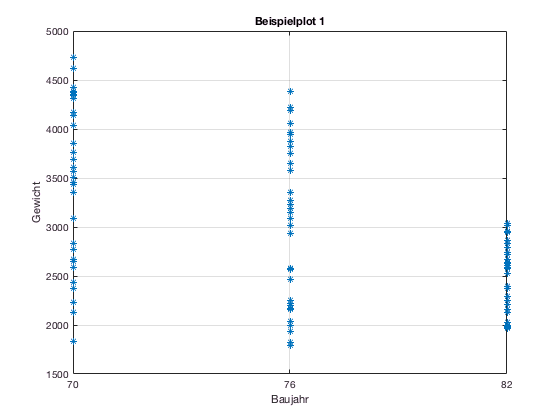


clear
close all


load carsmall.mat

Wenn wir nun das Skript ausführen, sehen wir unterschiedliche Variablen im Workspace. Diese können wir uns mit dem Befehl  "whos" auch in der Command Line anzeigen lassen. So bekommen wir einen ersten Überblick. Anschließend können wir mit unterschiedlichen Funktionen die Daten näher untersuchen:

% Baujahr
min(Model_Year)
max(Model_Year)
mean(Model_Year)
unique(Model_Year)

% Gewicht
[val, idx] = min(Weight)
Model(idx,:)

Mittelwerte pro Jahr berechnen:

bJahr_70 = Model_Year == 70;
bJahr_76 = Model_Year == 76;
bJahr_82 = Model_Year == 82;

mean( Weight(bJahr_70) )
mean( Weight(bJahr_76) )
mean( Weight(bJahr_82) )

Horsepower(bJahr_82)

bJahr_82_new = (Model_Year == 82) & ~isnan(Horsepower);
mean( Horsepower(bJahr_82_new) )


Grafische Darstellung der Daten:

figure
plot(Model_Year, Weight, '*')
xlabel('Baujahr')
ylabel('Gewicht')
title('Beispielplot 1')
grid on

% Alle Eigenschaften anzeigen:
get(gca)

% Werte der Eigenschaft 'XTick' anzeigen:
get(gca,'XTick')

% Werte der Eigenschaft 'XTick' setzen:
set(gca,'XTick',[70 76 82])

## Tutorial 2: Aufgabe

Der folgende Plot wurde ebenfalls aus den Daten generiert, die mit "load carsmall.mat" eingelesen wurden. 

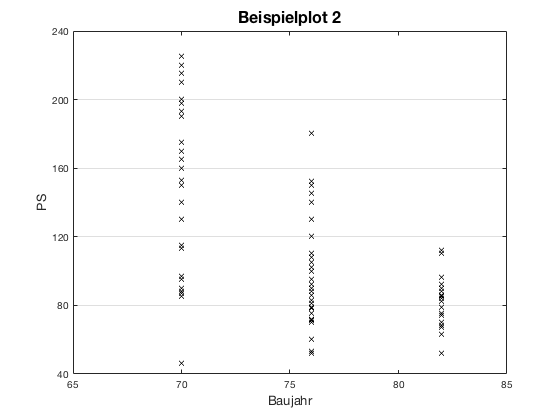

Versucht diesen Plot bitte möglichst genau darzustellen! In dem nächsten Tutorial wird die Lösung veröffentlicht.

**Hinweis:** Beachtet bitte die Eigenschafte, die mit "get(gca)" ausgegeben werden und verändert diese mit "set(gca, ...)".